# When the power spectrum isn't as useful as the PSD

This script was developed to demonstrate the concepts that are covered in the MATLAB Tech Talk on Power Spectrum and Power Spectral Density. We start by looking at the power spectrum of a time signal with two dominant sinusoids. By moving the freqeuncy of the second sinusoid, you can see how the interaction between the two changes the power spectrum to look more like a power density spectrum, hence why singals with broadbacnd noise is usually analyzed with a PSD instead of power. 

## Create time signal

Create a signal with 2 sine waves. One has a frequency of 100 Hz, the other has a variable freqeuncy given by the slider. 

1st Frequency: 100 Hz

clear 
fs = 500;
t = 0:1/fs:1-1/fs;
N = length(t); % Number of samples
A1 = 4;
A2 = 4;      % Amplitude
f1 = 100;
f2 =100.4; % Frequency

xn = A1*sin(2*pi*t*f1) + A2*sin(2*pi*t*f2); % Time signal with two sine waves

## Calculate the Power Spectrum

When the two freqeuncies are far apart from each other their spectra don't overlap and the peak value is the true power. As they get closer to each other and interact, then the peak no longer represents true power but is more closely described as power density. 

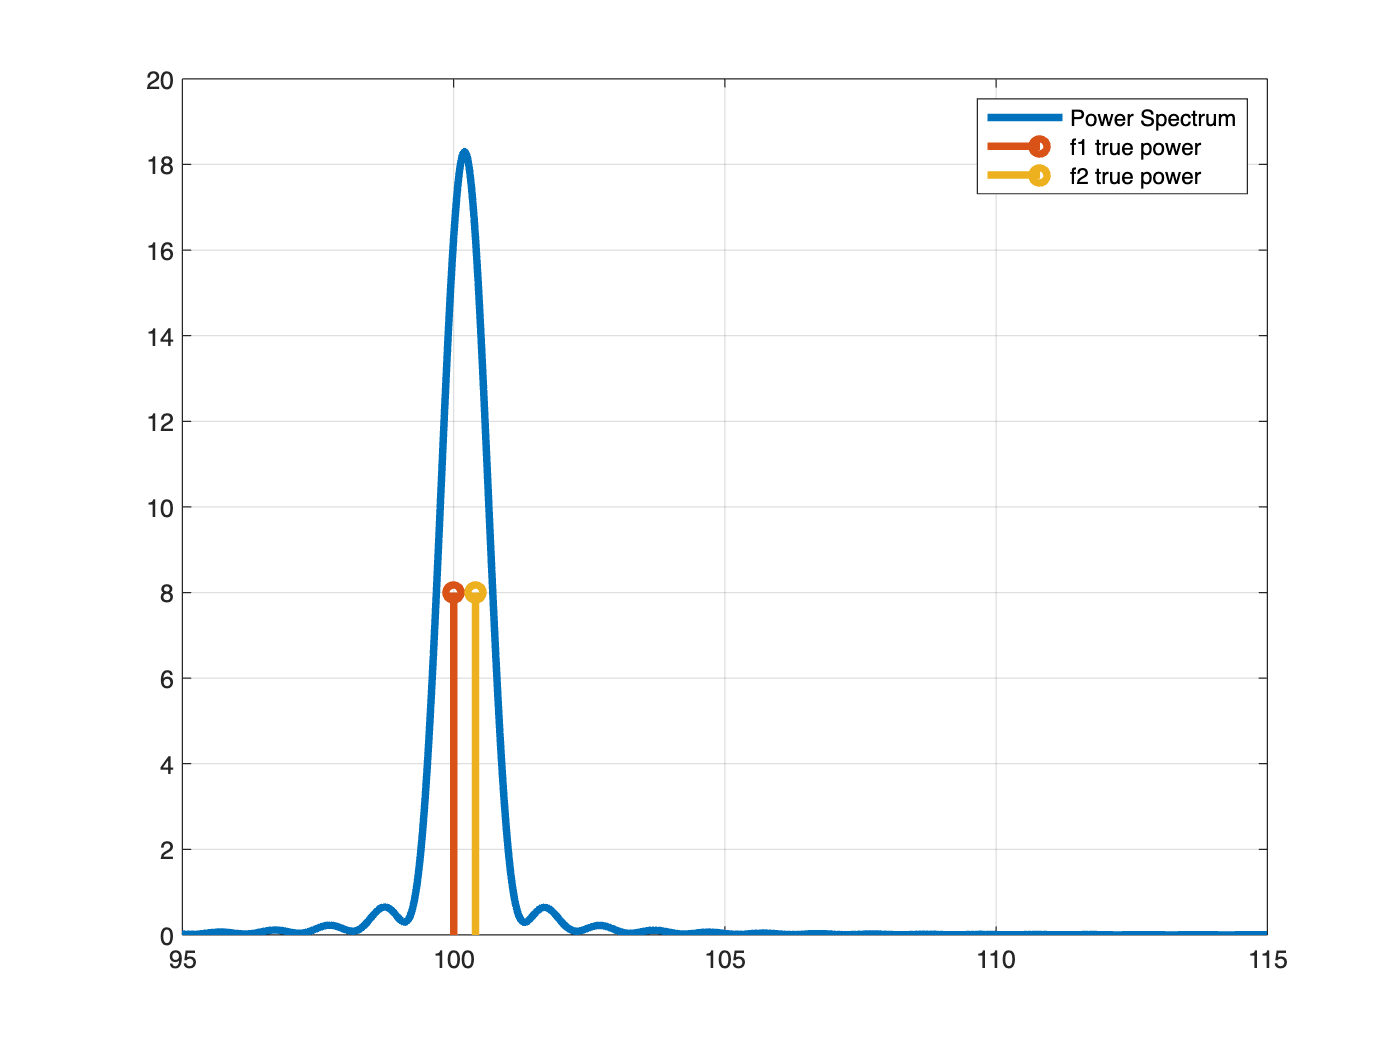

lt = 20000;
dft = fft(xn, lt);
xk = 1/N^2 * abs(dft).^2;

xk = xk(1:lt/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

freq = 0:fs/lt:fs/2;

close
plot(freq, xk, 'LineWidth', 3)
grid on
axis([95, 115, 0, 20])
hold on
stem(f1, 0.5*A1^2, 'LineWidth', 3);
stem(f2, 0.5*A2^2, 'LineWidth', 3);
legend('Power Spectrum', 'f1 true power', 'f2 true power');

## Multiple broadband signals contribute to a single peak in the power spectrum

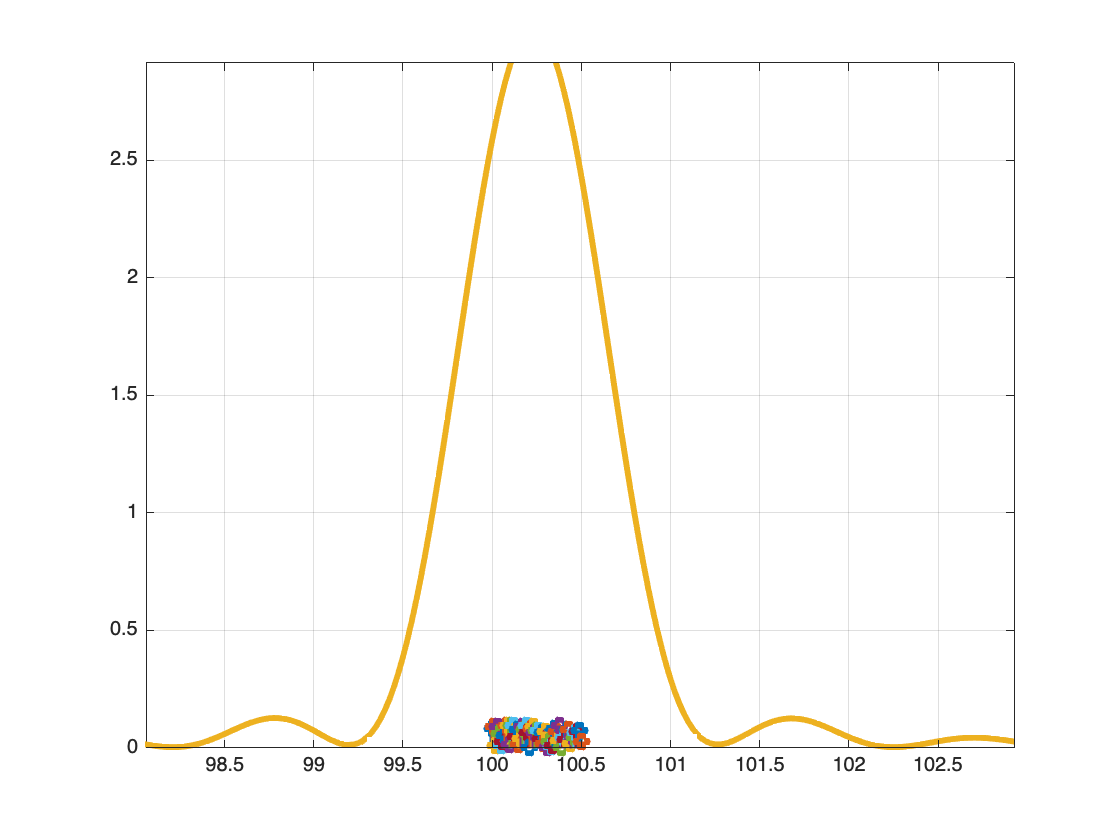

figure
xn = zeros(1, length(t));
for i = 0:50
    f = 100+i*.01;
    A = rand(1)*.1;
    xn = xn + A*sin(2*pi*t*f);
    stem(f, A, 'LineWidth', 3);
    axis([100, 100.5, 0, 0.1]);
    hold on
    grid on
    pause(0.01)
end
lt = 20000;
dft = fft(xn, lt);
xk = 1/N^2 * abs(dft).^2;

xk = xk(1:lt/2+1); % One-sided
xk(2:end-1) = 2*xk(2:end-1); % Double values except for DC and Nyquist

freq = 0:fs/lt:fs/2;
plot(freq, xk, 'LineWidth', 3)

axes_start = [100, 100.5, 0, 0.1];
axes_end = [98, 103, 0, 3];
for bin = 1:100
    axis(axes_start + (axes_end - axes_start)*bin/100);
    pause(0.01);
end